# Plan Excavator Manipulator Motion based on Lidar Data

Plan a path for a the excavator manipulator, in an environment that may contain obstacles, by using a motion planner.

A rigid body tree of the manipulator has been exported from Solidworks to URDF, and can be imported into MATLAB.

clear, close all
prj = currentProject;

urdfFilePath = fullfile(prj.RootFolder,"..","..","ExcavatorCADFiles","URDF_MathScavator9000_flat","MathScavator9000_flat","urdf","MathScavator9000_flat.SLDASM.urdf");
excavatorRBT = importrobot(urdfFilePath)

excavatorRBT =   rigidBodyTree with properties:

     NumBodies: 4
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base_chassis_link'  'chassis_boom_link'  'boom_stick_link'  'stick_bucket_link'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'


clearCollision(excavatorRBT.Base) %remove collision box from the base to avoid clipping into the map

Currently, "show" opens a new figure and embeds a non-interactive representation in the livescript. A workaround might be to use animated playback: [https://komodo.mathworks.com/main/gecko/view?Record=2646618](https://komodo.mathworks.com/main/gecko/view?Record=2646618) 

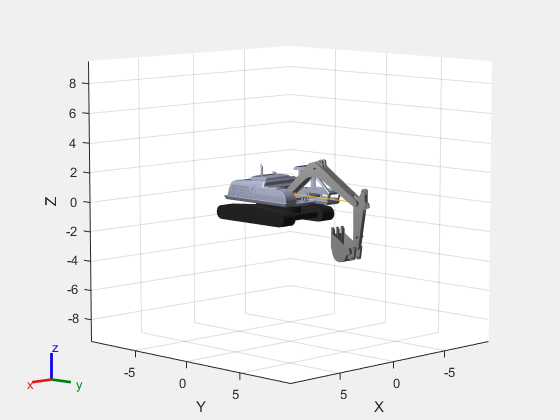

show(excavatorRBT);

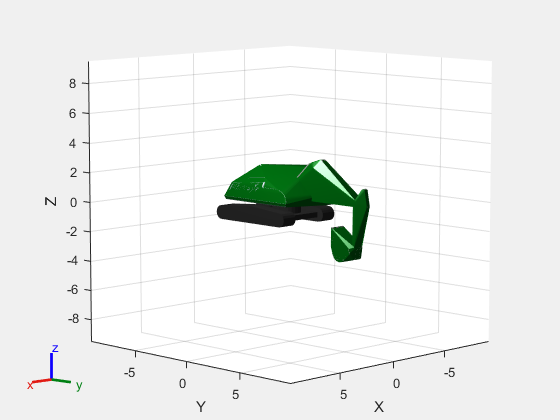

show(excavatorRBT,"Collisions","on");

In our convention, x is pointing in the forward direction of the excavator. Rotate the RBT by 90 degrees around Z to match.

tform = eul2tform([-pi/2,0,0]); 
excavatorRBT = setRigidBodyTreeRotation(excavatorRBT, tform);
excavatorRBT.DataFormat = 'row';

## Decompose the Collision Mesh

The collision mesh for the boom is too conservative, as it fits a convex hull around the part. Decompose the boom mesh to get a more accurate collision mesh.

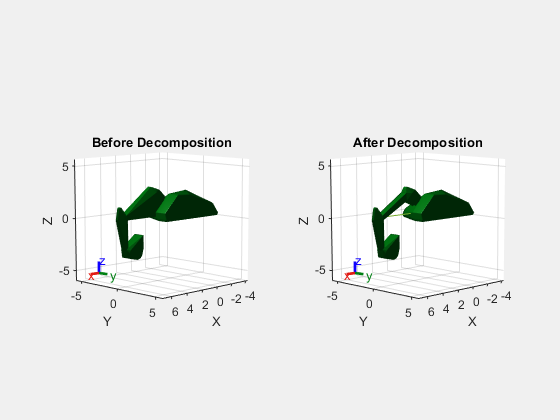

excavatorOriginal = copy(excavatorRBT);
opts = vhacdOptions("IndividualMesh", "MaxNumConvexHulls",2); %decompose into 2 parts

bodyIdxToReplace = 4;
% 1. Get current body and clear collision mesh
currBody = excavatorRBT.Bodies{bodyIdxToReplace};
clearCollision(currBody);

% 2. Get Corresponding visual data
vizData = getVisual(excavatorRBT.Bodies{bodyIdxToReplace});

% 3. If visual data, decompose visual data
if ~isempty(vizData)
    collisionArray = collisionVHACD(vizData(1).Triangulation,opts);

    % 4. Add each collision mesh to the rigid body
    for j = 1:numel(collisionArray)
        addCollision(currBody,collisionArray{j});
    end
end

tiledlayout(1,2);
nexttile
show(excavatorOriginal,Visuals="off",Collisions="on");
title("Before Decomposition")
axis auto
nexttile
show(excavatorRBT,Visuals="off",Collisions="on");
title("After Decomposition")
axis auto

## Create Environment from Lidar Data

We receive Lidar data from the game engine which we can use to create our environment.

To generate new Lidar measurements in the Unreal environment, run [createExamplePointCloudMeasurement.mlx](matlab:open('createExamplePointCloudMeasurement.mlx'))

exampleLidarPointClouds = load("exampleLidarPointClouds.mat").exampleLidarPointClouds;
lidarSensorOffsets = load("lidarSensorParameters.mat").lidarSensorOffsets;

[exampleLidarPointClouds.Front_Lidar.LocalTranslation, exampleLidarPointClouds.Front_Lidar.LocalRotation] = ...
    transformLocalLidarPose(lidarSensorOffsets.frontLidar.relativeTranslation, lidarSensorOffsets.frontLidar.relativeRotation);

[exampleLidarPointClouds.Rear_Lidar.LocalTranslation, exampleLidarPointClouds.Rear_Lidar.LocalRotation] = ...
    transformLocalLidarPose(lidarSensorOffsets.rearLidar.relativeTranslation, lidarSensorOffsets.rearLidar.relativeRotation);

[exampleLidarPointClouds.Left_Lidar.LocalTranslation, exampleLidarPointClouds.Left_Lidar.LocalRotation] = ...
    transformLocalLidarPose(lidarSensorOffsets.leftLidar.relativeTranslation, lidarSensorOffsets.leftLidar.relativeRotation);

[exampleLidarPointClouds.Right_Lidar.LocalTranslation, exampleLidarPointClouds.Right_Lidar.LocalRotation] = ...
    transformLocalLidarPose(lidarSensorOffsets.rightLidar.relativeTranslation, lidarSensorOffsets.rightLidar.relativeRotation);

Merge the lidar measurements into a single point cloud of the environment.

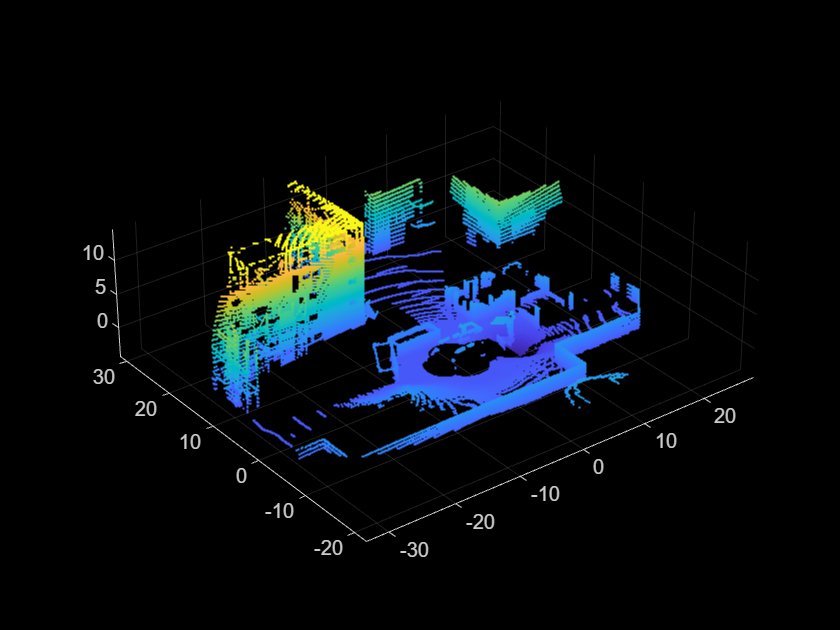

mergedPointCloud = mergeLidarPointClouds(exampleLidarPointClouds);
figure
pcshow(mergedPointCloud)

**Remove the excavator itself from the point cloud.**

Use the rigid body tree and fit a rectangular bounding box around the mesh of each body.

% Set rigid body tree configuration to the configuration set during the measurement
rbtState = deg2rad([0, 0, 0, 0]);

selfObjectROI = [];
inflationRatio = 0.1; %inflate body size to catch edge cases
rbtBodies = excavatorRBT.Bodies;
for ii=2:numel(rbtBodies)
    % Get transform of current body
    tform_body = rigidtform3d(getTransform(excavatorRBT, rbtState, rbtBodies{ii}.Name));
    % Extract triangular mesh of current body
    vizData = getVisual(rbtBodies{ii});
    % Get the mesh points at the given transformation
    tri = transformPointsForward(tform_body, vizData.Triangulation.Points);
    
    % Get minimum and maximum points of the mesh to define the rectangular bounding box
    roi = ([min(tri); max(tri)]);

    % Inflate bounding box to catch edge points
    inflationFactor = inflationRatio*diff(roi);
    roi(1,:) = roi(1,:) - inflationFactor;
    roi(2,:) = roi(2,:) + inflationFactor;

    selfObjectROI(ii,:) = roi(:)';
end

Remove self object from point cloud.

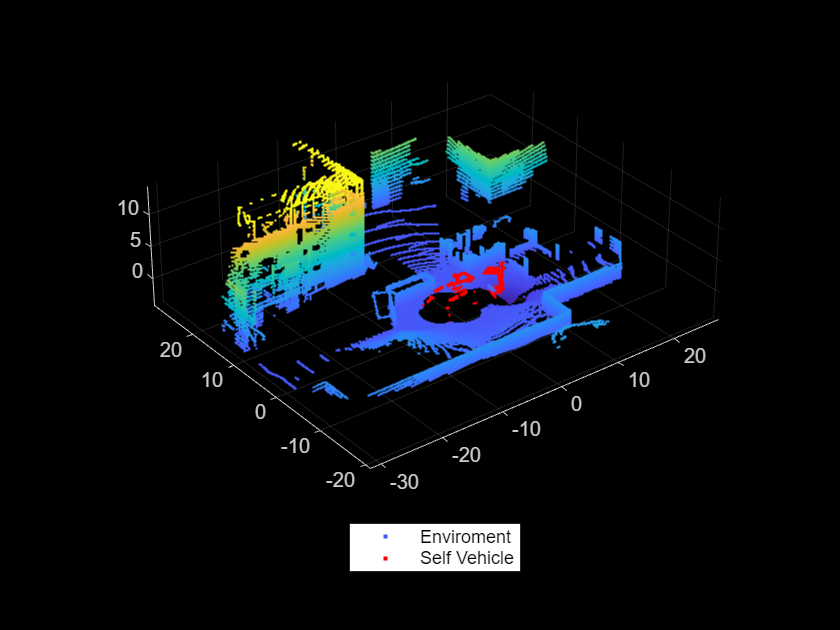

indicesSelfObject = [];
for ii=1:size(selfObjectROI,1)
    indicesSelfObject = [indicesSelfObject; findPointsInROI(mergedPointCloud, selfObjectROI(ii,:))];
end
indicesEnvironment = setdiff(uint32(1:mergedPointCloud.Count),indicesSelfObject);


environmentPointCloud = select(mergedPointCloud, indicesEnvironment);
environmentPointCloud = pcdenoise(environmentPointCloud);

figure
pcshow(environmentPointCloud)
hold on
pcshow(select(mergedPointCloud, indicesSelfObject).Location,'r');
legend('Enviroment','Self Vehicle','Location','southoutside','Color',[1 1 1])
hold off

## Create Motion Planner

We represent the environment using a 3d occupancy map which we can hand over to the planner.

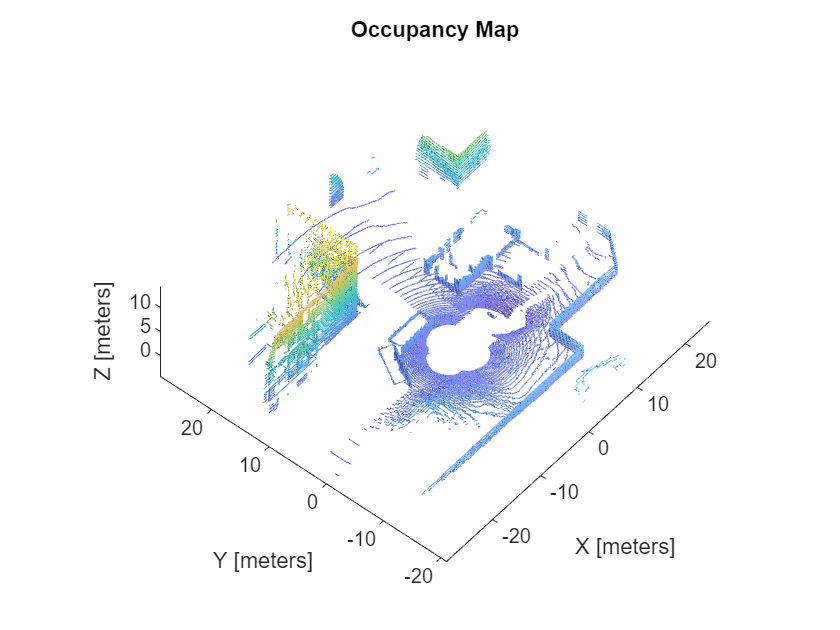

omap3D = occupancyMap3D(10);
pose = [0 0 0 1 0 0 0];
maxRange = double( max(environmentPointCloud.Location, [], 'all') );
insertPointCloud(omap3D, pose, double(environmentPointCloud.Location), maxRange)
figure;
show(omap3D)
axis equal

Create the motion planner. Use the `manipulatorRRT` object, which is designed to plan motion for robots with a tree-like structure.

planner = manipulatorRRT(excavatorRBT, {}, "Map",omap3D);

Next, configure the planner. Scale the connection distance and validation distance to the task. Determining these values requires some trial and error.

planner.MaxConnectionDistance = 1;
planner.ValidationDistance = 0.03;

The valid motion range of the arm is already constrained by the joint limits. Set the planner to ignore self-collisions to avoid issues with the convex collision hulls.

planner.IgnoreSelfCollision = true;
planner.SkippedSelfCollisions = "parent"; 

## Set Up Planning Problem

Define the start and goal poses. The planner attempts to find a collision-free path between these two poses.

initialState = deg2rad([0, -10, 40, 0]);
targetState = deg2rad([120, 40, 20, 0]);

Visualize the environment and the start and the goal poses of the excavator manipulator.

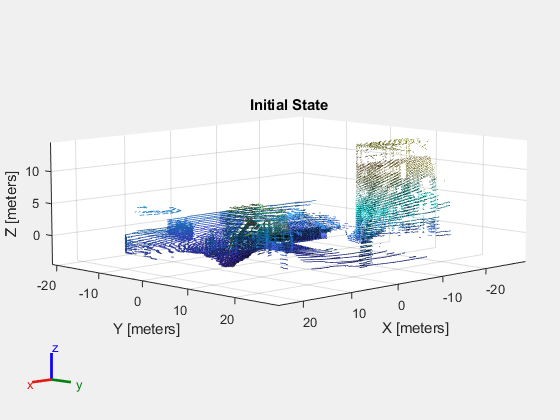

figure
show(excavatorRBT,initialState, "Collisions","off");
hold on
show(omap3D)
axis equal
hold off
title("Initial State")

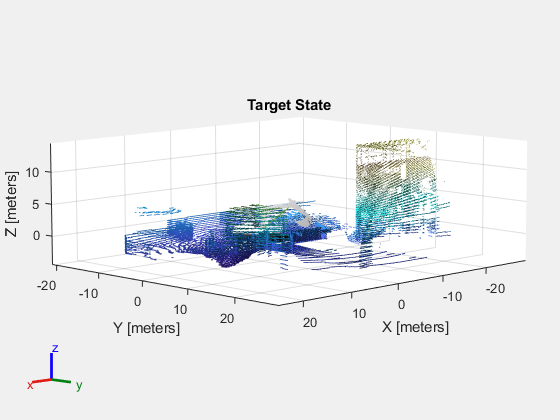

figure
show(excavatorRBT,targetState, "Collisions","off"); 
hold on
show(omap3D)
axis equal
hold off
title("Target State")

## Plan Collision-Free Path

Set the random seed, for repeatability, and then run the planner to compute a collision-free path. 

rng(20); % For repeatability
path = plan(planner,initialState,targetState);

Because of the design of the planner, the initial returned path may be inefficient and appear somewhat random. Use the `shorten` routine to iterate on the path and find a more optimized solution. Then smooth the results by interpolating between the planned poses.

shortenedPath = shorten(planner,path,20);
smoothPath = interpolate(planner,shortenedPath,5);

Visualize the planned path in MATLAB. This output shows the outcome of the planner using the simplified model and environment.

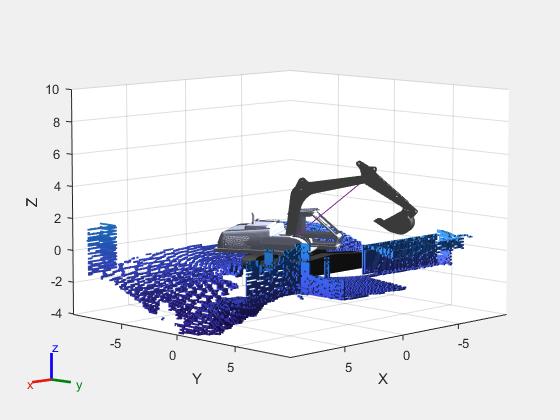

figure
ax = show(excavatorRBT,initialState,Collisions="off");
zlim([-4 10])
drawnow
hold on
show(omap3D,Parent=ax);

pause(0.5)
rc = rateControl(10);
for ii = 1:size(smoothPath,1)
    show(excavatorRBT,smoothPath(ii,:),Parent=ax,Collisions="off",FastUpdate=true,PreservePlot=false);
    waitfor(rc);
end
hold off

## Convert Path to Trajectory

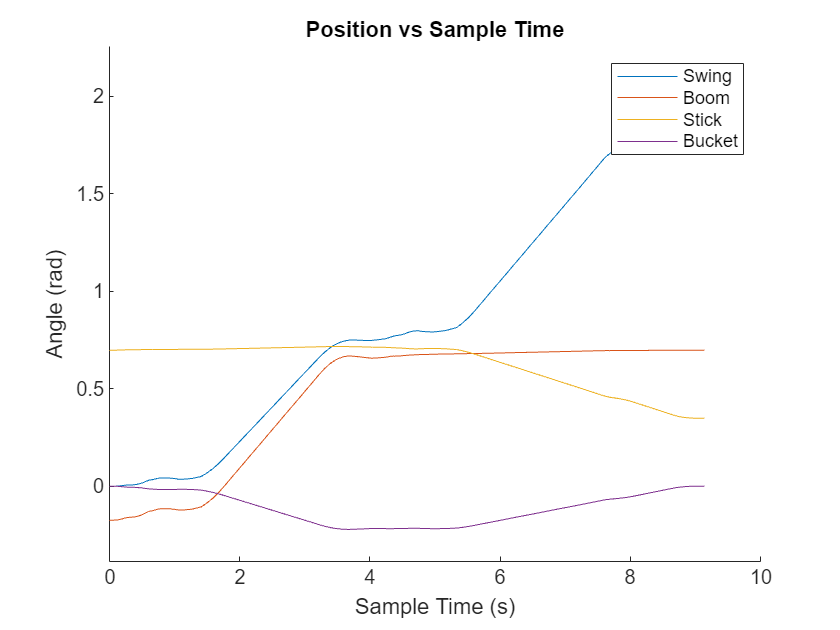

velocityLimits = repmat([-pi/8, pi/8], 4, 1);
accelerationLimits = repmat([-pi/4, pi/4], 4, 1);
[q, qd, qdd, t] = contopptraj(smoothPath', velocityLimits, accelerationLimits, "NumSamples", 200);

figure
title("Position vs Sample Time")
ylim("padded")
hold on
plot(t,q(1,:)) 
plot(t,q(2,:)) 
plot(t,q(3,:)) 
plot(t,q(4,:)) 
xlabel("Sample Time (s)")
ylabel("Angle (rad)")
legend(["Swing", "Boom", "Stick", "Bucket"])
hold off

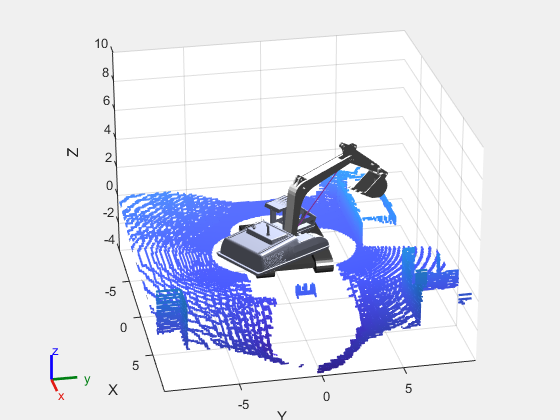

figure
ax = show(excavatorRBT,initialState,Collisions="off");
zlim([-4 10])
drawnow
hold on
show(omap3D,Parent=ax);

pause(0.5)
rc = rateControl(10);
for ii = 1:size(q',1)
    show(excavatorRBT,q(:,ii)',Parent=ax,Collisions="off",FastUpdate=true,PreservePlot=false);
    waitfor(rc);
end
hold off



manipulatorReferenceTrajectory = Simulink.SimulationData.Dataset;
manipulatorReferenceTrajectory = addElement(manipulatorReferenceTrajectory, timeseries(q(1,:),t), "SwingTrajectory");
manipulatorReferenceTrajectory = addElement(manipulatorReferenceTrajectory, timeseries(q(2,:),t), "BoomTrajectory");
manipulatorReferenceTrajectory = addElement(manipulatorReferenceTrajectory, timeseries(q(3,:),t), "StickTrajectory");
manipulatorReferenceTrajectory = addElement(manipulatorReferenceTrajectory, timeseries(q(4,:),t), "BucketTrajectory");
fpath = fullfile(prj.RootFolder,"MotionPlanning","manipulatorReferenceTrajectory.mat");
save(fpath, "manipulatorReferenceTrajectory");